Original

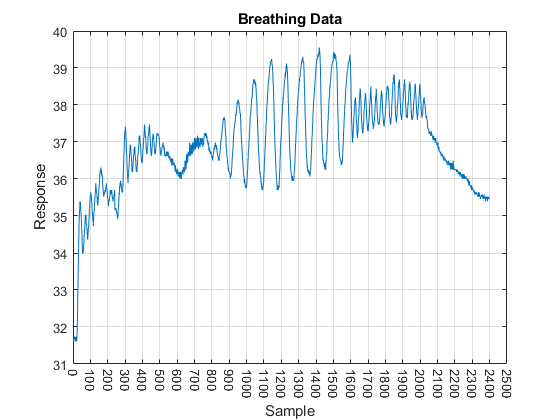

fileName = 'BreathingCapture3.mat';
load(fullfile(pwd, fileName));
sample = breathingData(:,1);
data = breathingData(:,2);

figure
plot(sample, data)
grid on
set(gca,'XTick',0:100:2500)
xtickangle(270)
title('Breathing Data')
xlabel('Sample')
ylabel('Response')

Equalized and filtered

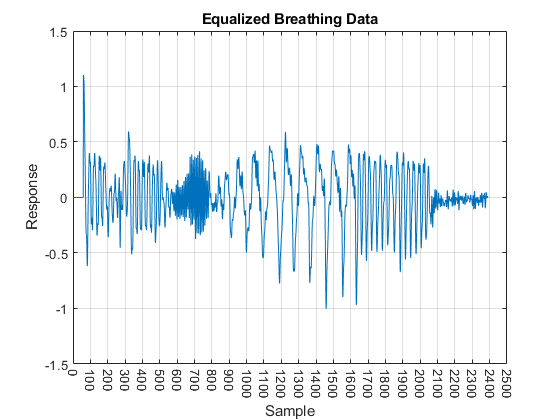

fileName = 'BreathingCapture3SystemTest.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
equalized = outData(:,3); % equalized signal
low_rate = outData(:,4); % low rate filter output
mid_rate = outData(:,5);
high_rate = outData(:,6);
stdLF = outData(:,7); % running low rate std
stdMF = outData(:,8);
stdHF = outData(:,9);
warning_logic = outData(:,10); % warning logic code

figure
plot(sample, equalized)
grid on
set(gca,'XTick',0:100:2500)
xtickangle(270)
title('Equalized Breathing Data')
xlabel('Sample')
ylabel('Response')

Low rate filter

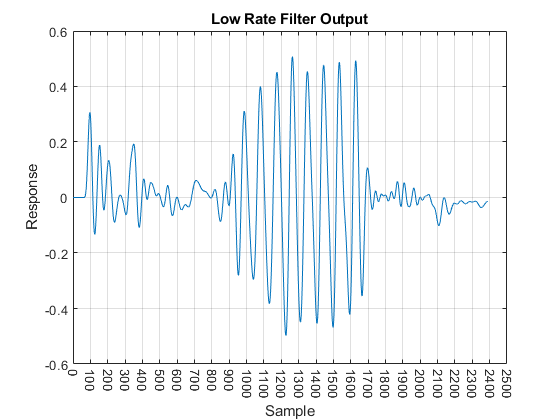

figure
plot(sample, low_rate)
grid on
set(gca,'XTick',0:100:2500)
xtickangle(270)
title('Low Rate Filter Output')
xlabel('Sample')
ylabel('Response')

Mid rate filter

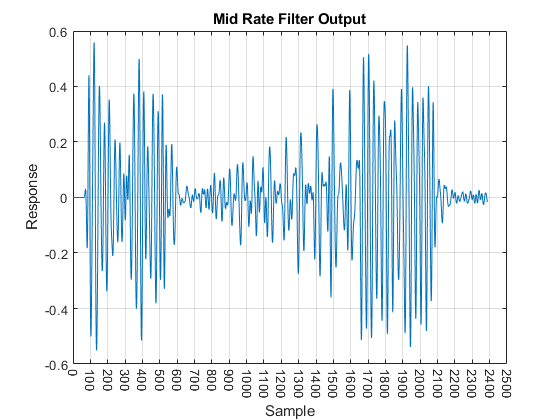

figure
plot(sample, mid_rate)
grid on
set(gca,'XTick',0:100:2500)
xtickangle(270)
title('Mid Rate Filter Output')
xlabel('Sample')
ylabel('Response')

High rate filter + std

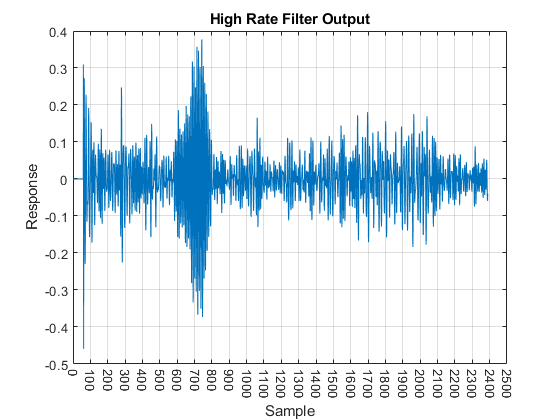

figure
plot(sample, high_rate)
grid on
set(gca,'XTick',0:100:2500)
xtickangle(270)
title('High Rate Filter Output')
xlabel('Sample')
ylabel('Response')

Running stats comparison

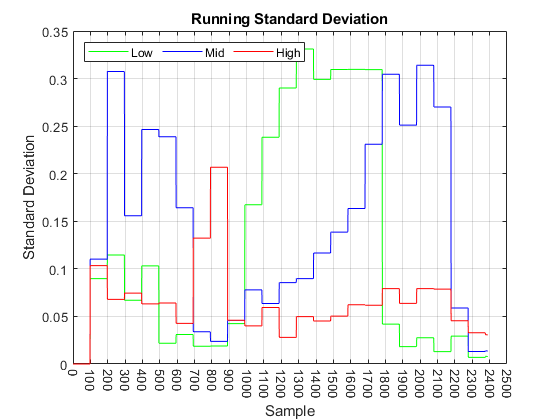

figure
plot(sample, stdLF,'g')
hold on
plot(sample, stdMF,'b')
plot(sample, stdHF,'r')
grid on
set(gca,'XTick',0:100:2500)
xtickangle(270)
title('Running Standard Deviation')
xlabel('Sample')
ylabel('Standard Deviation')
legend({'Low','Mid','High'},'Location','northwest','NumColumns',3)

Warning logic code

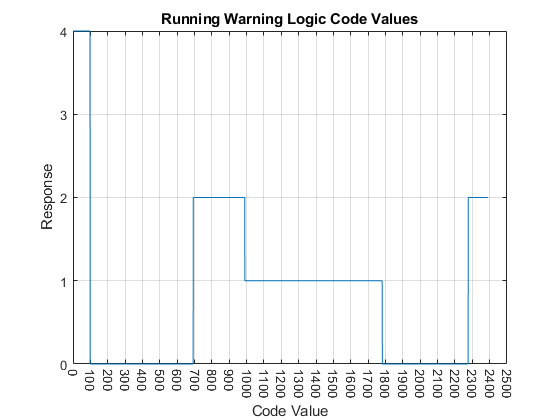

figure
plot(sample, warning_logic)
grid on
set(gca,'ytick',0:4)
set(gca,'XTick',0:100:2500)
xtickangle(270)
title('Running Warning Logic Code Values')
xlabel('Code Value')
ylabel('Response')